# First Question

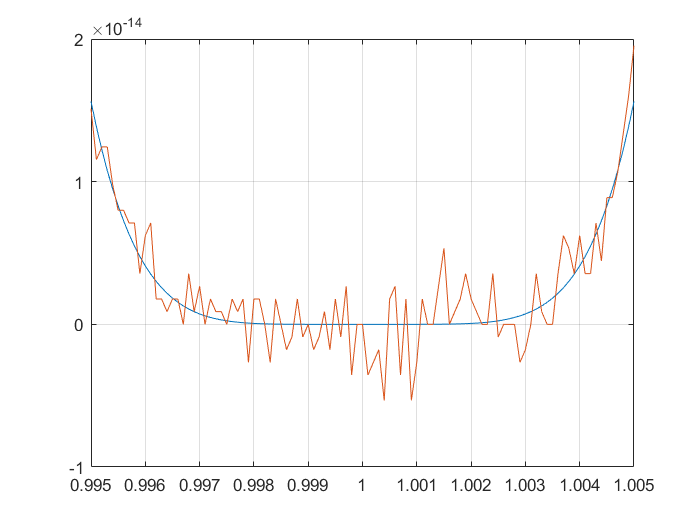

y = 	1.0e+-13 *

    0.1510    0.1155    0.1243    0.1243    0.0977    0.0799    0.0799    0.0711    0.0711    0.0355    0.0622    0.0711    0.0178    0.0178    0.0089    0.0178    0.0178         0    0.0355    0.0089    0.0266         0    0.0178    0.0089    0.0089         0    0.0178    0.0089    0.0178   -0.0266    0.0178    0.0178         0   -0.0266    0.0178         0   -0.0178   -0.0089    0.0178   -0.0089         0   -0.0178   -0.0089    0.0089   -0.0178    0.0178   -0.0089    0.0266   -0.0355         0


x = linspace(0.995,1.005,101);
figure();
xlabel("x");
ylabel("Polys!");
plot(x,polyFirstStyle(x));
hold on
plot(x,polySecondStyle(x));

First way to display the Polynomial

function y = polyFirstStyle(x)
y = (x-1).^6;
end

Second way to display the Polynomial

function y = polySecondStyle(x)
y = x.^6-6.*(x.^5)+15.*(x.^4)-20.*(x.^3)+15.*(x.^2)-6.*x+1
end

Asked Question : why there are differences ?!

Answer : in the first type of calculation there is just multiplication error but in the second way of calculation there are many kind of errors such as  multiplication , summation ( in each addition there is a cancellation error since all numbers are being saved in binary basis so there is not a fixed way to save definite value of number therefore some values are left and by having addition to happen multiple times the errors get more and more so that the total error becomes bigger than the error which happens in the first kind of calculation.